## Test saved workspaces

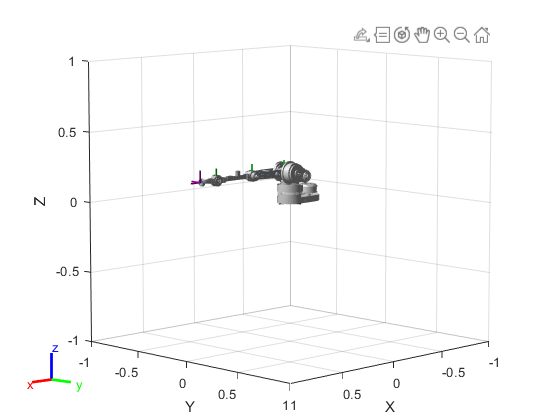

clear all 
close all
robot=importrobot('Arbot_Rev2_1.urdf');
% Add gravity
gravityVec = [0 0 -9.80665];
robot.Gravity = gravityVec; 
inch = 0.0254;
half_inch = inch / 2;
% Add another massless coordinate frame for the end effector

eeOffset = 0.150;
eeBody = robotics.RigidBody('end_effector');
eeBody.Mass = 0;
eeBody.Inertia = [0 0 0 0 0 0];
setFixedTransform(eeBody.Joint,trvec2tform([eeOffset 0 0]));
figure(1);
addBody(robot,eeBody,'L4');
axes=show(robot,'PreservePlot', true,'Frames','off');
axes.CameraPositionMode = 'auto';


workspace = load('ARbot_workspace_iterative_P_A_const.mat');
ikSols = load('ikLookupiterativeP_A_const.mat');
workspace_points = workspace.P_A;
sizeOfWorkspace = size(workspace_points);
if sizeOfWorkspace(2) > 3
    workspace_points(:,4) = [];
end
ikLookup = ikSols.ikLookup;

q = robot.homeConfiguration;
show(robot,q, 'PreservePlot', true,'Frames','off');
hold on

## Show partial solutions

% workspace = load('ARbot_workspace_iterative_P_A.mat');
% ikSols = load('ikLookupiterativeP_A.mat');
% workspace_points = workspace.P_A;
% sizeOfWorkspace = size(workspace_points);
% if sizeOfWorkspace(2) > 3
%     workspace_points(:,4) = [];
% end
% ikLookup = ikSols.ikLookup;

for i=1:length(workspace_points)
    a = i/180*pi;
    x = workspace_points(i,1);
    y = workspace_points(i,2);
    z = workspace_points(i,3);
    plot3(x,y,z,'r.');
    pause(0.001);
    hold on
end

q = robot.homeConfiguration;
i = 1;
% gik.RigidBodyTree = robot;
%for i = 1:size(ikLookup,1)
q(1).JointPosition = ikLookup(i,1);
q(2).JointPosition = ikLookup(i,2);
q(3).JointPosition = ikLookup(i,3);
q(4).JointPosition = ikLookup(i,4);
show(robot,q, 'PreservePlot', true,'Frames','off');
hold on

i = floor(size(ikLookup,1) / 4);
q(1).JointPosition = ikLookup(i,1);
q(2).JointPosition = ikLookup(i,2);
q(3).JointPosition = ikLookup(i,3);
q(4).JointPosition = ikLookup(i,4);
show(robot,q, 'PreservePlot', true,'Frames','off');
hold on

i = floor(size(ikLookup,1) / 2);
q(1).JointPosition = ikLookup(i,1);
q(2).JointPosition = ikLookup(i,2);
q(3).JointPosition = ikLookup(i,3);
q(4).JointPosition = ikLookup(i,4);
show(robot,q, 'PreservePlot', true,'Frames','off');
hold on
% 
i = floor(size(ikLookup,1) * 3 / 4);
q(1).JointPosition = ikLookup(i,1);
q(2).JointPosition = ikLookup(i,2);
q(3).JointPosition = ikLookup(i,3);
q(4).JointPosition = ikLookup(i,4);
show(robot,q, 'PreservePlot', true,'Frames','off');
hold on


i = size(ikLookup,1);
q(1).JointPosition = ikLookup(i,1);
q(2).JointPosition = ikLookup(i,2);
q(3).JointPosition = ikLookup(i,3);
q(4).JointPosition = ikLookup(i,4);
show(robot,q, 'PreservePlot', true,'Frames','off');
hold on


## Show Full Solutions

% figure(2)
for i=1:length(workspace_points)
    a = i/180*pi;
    x = workspace_points(i,1);
    y = workspace_points(i,2);
    z = workspace_points(i,3);
    plot3(x,y,z,'r.');
    pause(0.001);
    hold on
end

for i=1:4:length(ikLookup)
    q(1).JointPosition = ikLookup(i,1);
    q(2).JointPosition = ikLookup(i,2);
    q(3).JointPosition = ikLookup(i,3);
    q(4).JointPosition = ikLookup(i,4);
    show(robot,q, 'PreservePlot', true,'Frames','off');
    hold on
end

## Show a sample trajectory


figure(3)
% safe via point for intermediate trajectories
safe_via_angles = [ 2.0027    0.9535    1.3824    0.7694] ;
J1_safe_angle = rad2deg(safe_via_angles(1)) - 90;
J1_safe_angle = deg2rad(J1_safe_angle);
safe_via_angles(1) = J1_safe_angle;

tf = 2;
tv = 1;
q0 = [ pi/2 0 0 0];
qv = safe_via_angles

% qf = ikLookup(floor(5/6*length(ikLookup)),:);
qf = ikLookup(20,:);

q = robot.homeConfiguration;
[theta] = traj6_v2(q0,qv,qf,tf,tv);

show(robot,q, 'PreservePlot', true,'Frames','on');
hold on
for i=1:length(workspace_points)
    a = i/180*pi;
    x = workspace_points(i,1);
    y = workspace_points(i,2);
    z = workspace_points(i,3);
    plot3(x,y,z,'c.');
    pause(0.001);
    hold on
end

for i = 1:length(theta)
    q(1).JointPosition = theta(i,1);
    q(2).JointPosition = theta(i,2);
    q(3).JointPosition = theta(i,3);
    q(4).JointPosition = theta(i,4);
    show(robot,q, 'PreservePlot', true,'Frames','off');
    pause(0.001);
    hold on
end
